y0 = [0; 0; 0];
tspan = linspace(0, 5);

v = 1;

[t, y] = sim_magnet(tspan, y0, v);

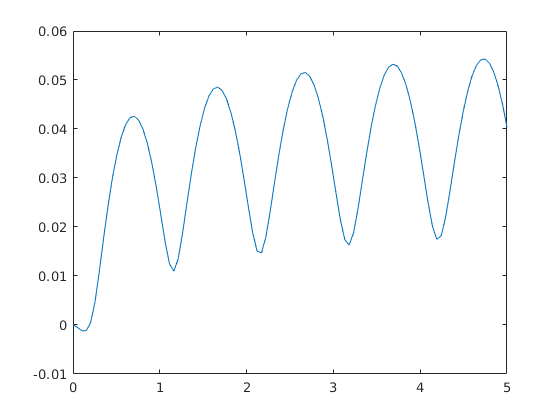

plot(t, y(:, 1))

function [t, y] = sim_magnet(tspan, y0, v_in)
    m = 0.05; % kg
    g = 9.8; %m/s^2
    L = 12;
    R = 5;
    
    f_rates = @(t, y) ( ...
        rates_current(y, v_in)...
    );
    
    [t, y] = ode45(f_rates, tspan, y0);
    
    function rates = rates_current(y, v_in) % provide u as a function of y
        % Velocity
        rates(1,1) = y(2);
        
        % Acceleration
        rates(2,1) = -F_iz(y(3), y(1)) - m*g;
        
        % Change in current (inductor)
        rates(3, 1) = (1/L)*(v_in - y(3)*R);
    end
end
